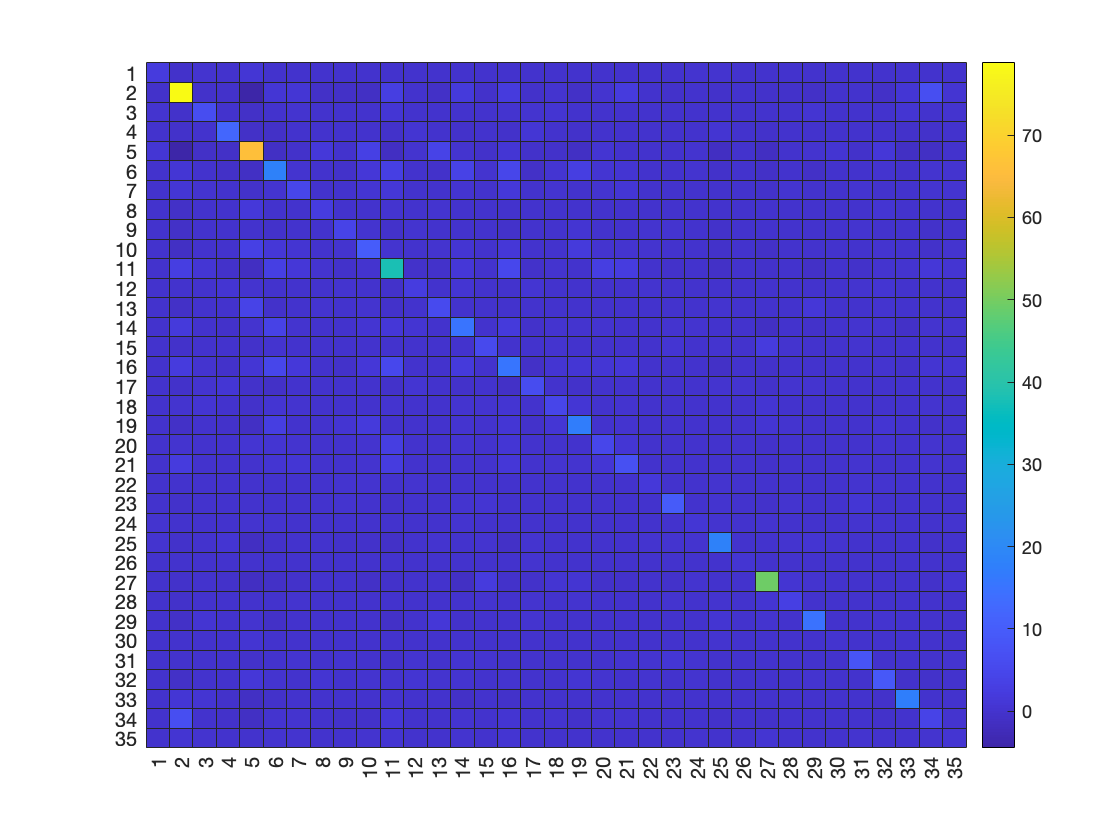

load('trace.mat')
%Q2

%a)
cov_trace = cov(trace);
corrcoef_trace = corrcoef(trace);
figure
heatmap(cov_trace);
colormap(parula)

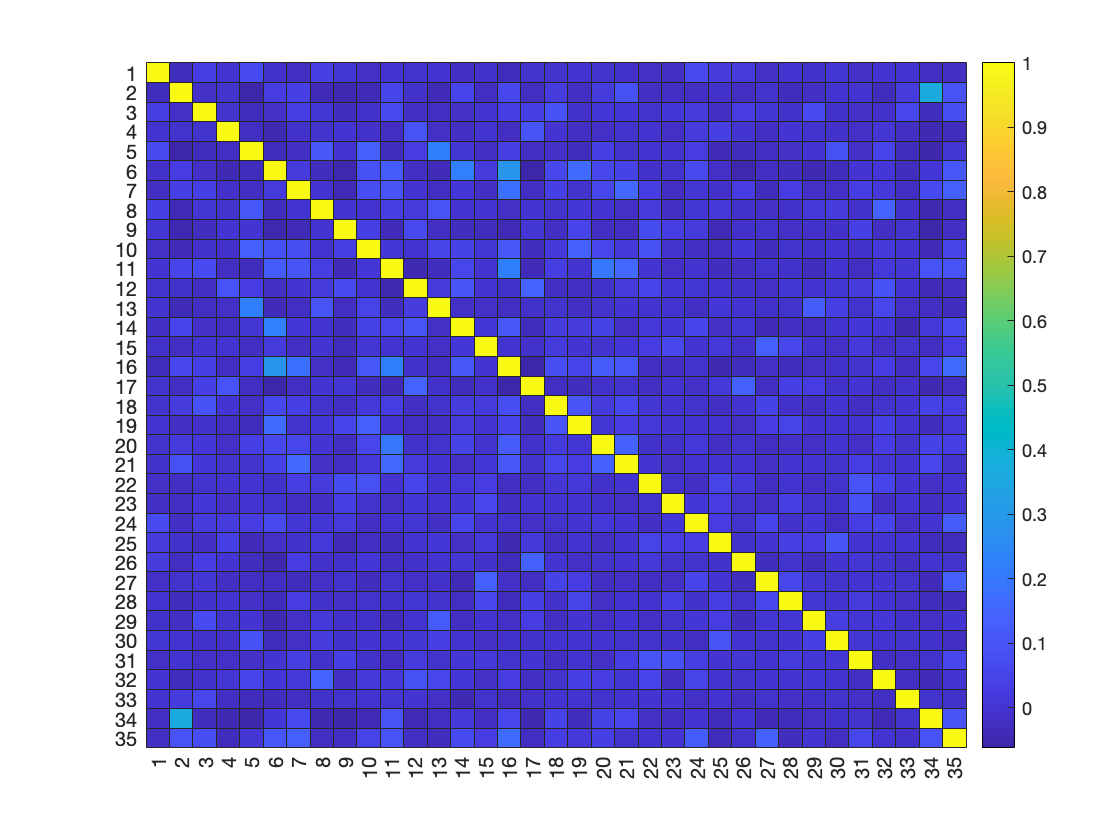

figure
heatmap(corrcoef_trace);
colormap(parula)


%b)
ztrace = zscore(trace);
covztrace = cov(ztrace);
corrcoefztrace = corrcoef(ztrace);
figure
heatmap(covztrace);
colormap(parula)

figure
heatmap(corrcoefztrace);
colormap(parula)

%after z scoring, covariance plot is normalized and similar to the
%correlation coefficient plot.

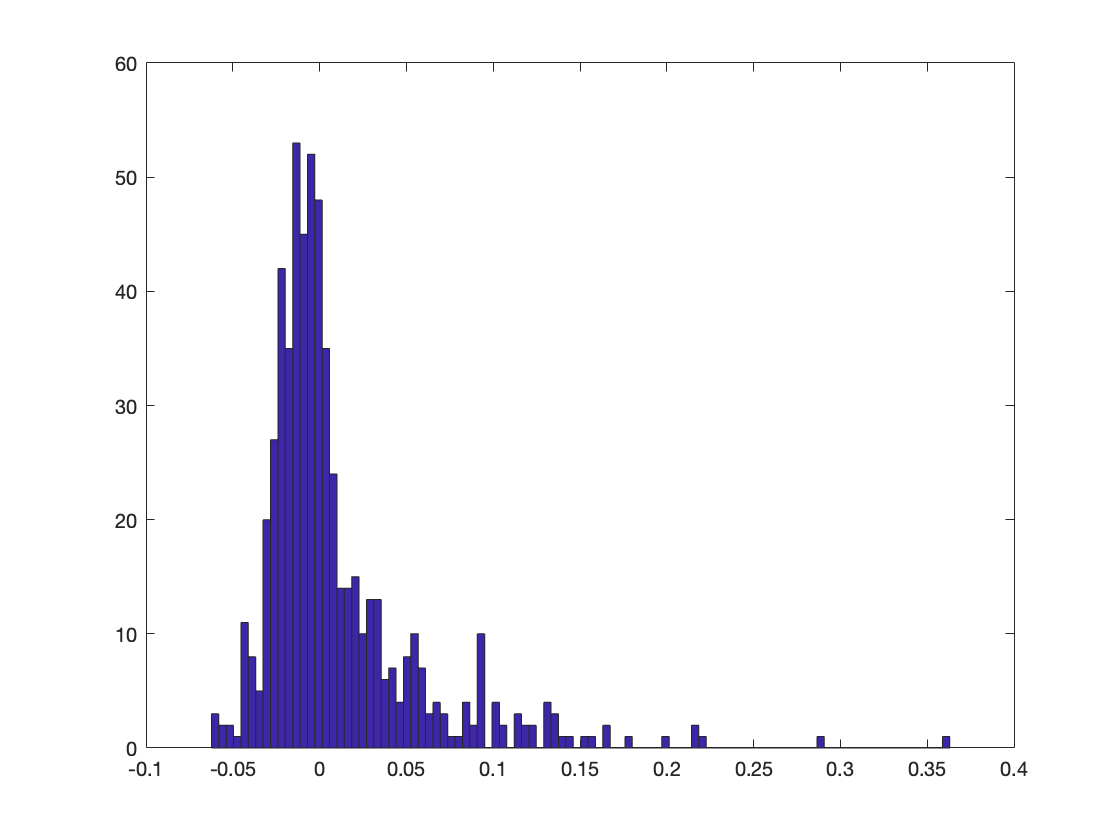


%c)
%number of distinct pairs will be (N*(N-1))/2
[paircov,N] = findpairs(corrcoef_trace);
figure
hist(paircov,100)

display(N)

N = 595

function [paircov,numpairs] = findpairs(cov)
paircov = [];
numpairs = (length(cov)*(length(cov)-1))/2;
for i = 2:length(cov)
    %(1,1) is not a unique pair, and we'll go down each row
    digtemp = [1:(i-1)];
    paircov = [paircov;cov(digtemp,i)];
end
paircov = paircov';

end